## Przygotowanie wzorcowych wektorów cech

### Wczytanie nagrania

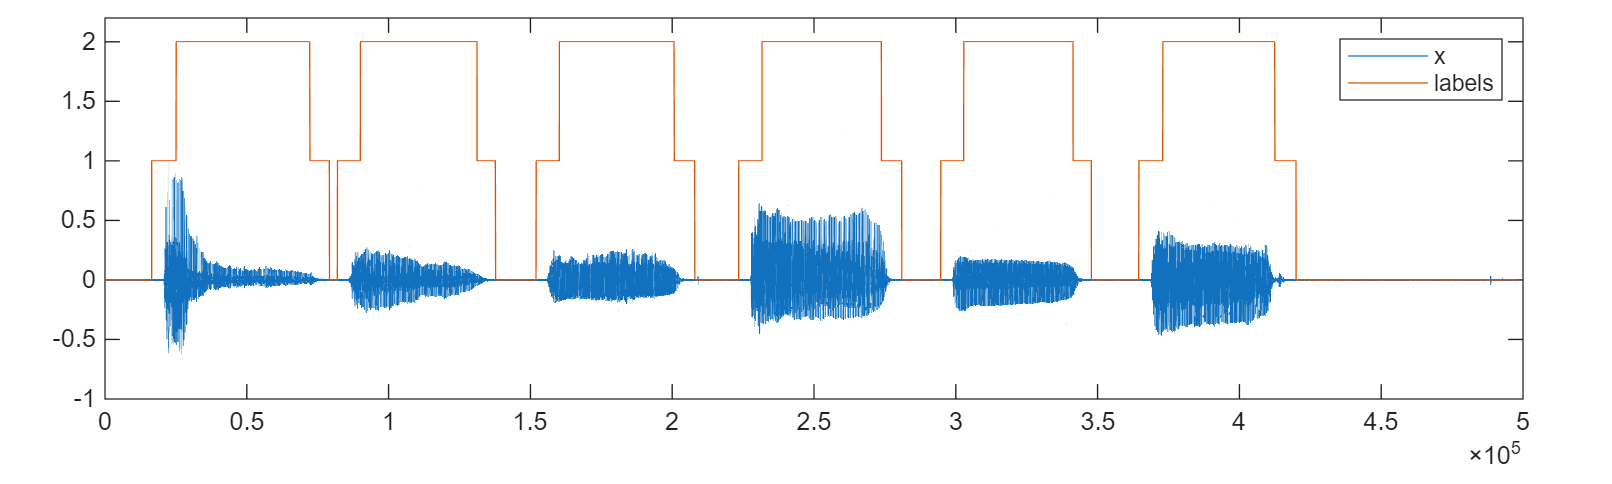

[x, fs] = audioread("aeiouy.wav");
x = x - mean(x);
x = x / max(x);

lbls = label(x, fs);

figure("Position", [0 0 1000 300]);
tiledlayout(1,1,'TileSpacing','Compact','Padding','Compact');
nexttile;

plot(x / max(x));
ylim([-1 2.2])
hold on;

plot(lbls);
legend("x", "labels")

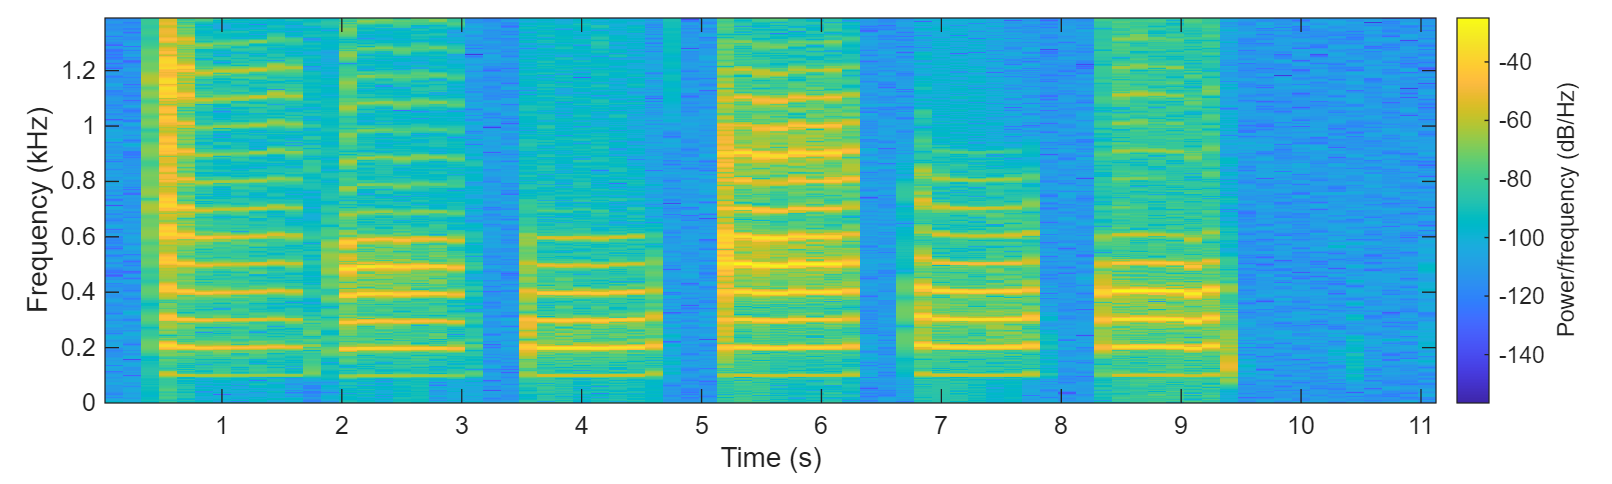

win = round(fs * 0.2);

[s, f, t] = spectrogram(x, win, round(win / 4), [], fs, 'yaxis');

figure("Position", [0 0 1000 300]);
tiledlayout(1,1,'TileSpacing','Compact','Padding','Compact');
nexttile;
spectrogram(x, win, round(win/4), [], fs, 'yaxis');

ylim([-0.00 1.39])

# Komentarz

Etykietowanie oddzielonych głosek działa poprawnie. Spektrogram wygląda tak jak się można spodziewać: wiele wyraźnych prążków odpowiadających kolejnym harmonicznym tonu podstawowego.

### Etykietowanie danych

W kolejnych kolumnach macierzy znajdują się:

- numer okienka

- numer prążka

- częstotliwość prążka

- numer etykiety

Częstotliwość bazowa dla danego okienka wyznaczana jest przez podzielenie częstotliwości prążka przez jego numer.

sel = [
     6, 12, 1192, 1
     7, 12, 1198, 1
     8, 12, 1200, 1
     9, 12, 1206, 1
    
    15, 12,  1184, 2
    16, 12,  1184, 2
    17, 12,  1171, 2
    18, 12,  1195, 2
    
    26,  6,  598, 3
    27,  6,  592, 3
    28,  6,  595, 3
    29,  6,  600, 3
    
    37, 12,  1192, 4 
    38, 12,  1187, 4
    39, 12,  1209, 4
    40, 12,  1203, 4
    
    47,  8,  807, 5
    48,  8,  804, 5
    49,  8,  802, 5
    50,  8,  808, 5
    
    57,  6,  606, 6
    58,  6,  608, 6
    59,  6,  606, 6
    60,  6,  606, 6
];

Dodatkowo określamy same etykiety dla naszych danych:

labels = ['a', 'e', 'i', 'o', 'u', 'y'];

### Wyznaczenie wektorów cech

Prostą cechą dla głosek dźwięcznych jest rozkład energii sygnału w kolejnych harmonicznych częstotliwości bazowej (F0). Znając jej wartość można wyznaczyć położenie harmonicznych i odczytać z transformaty Fouriera ich amplitudę bądź energię.

% liczba harmonicznych do analizy
n_peaks = 14;

% liczba próbek uczących
n_frames = size(sel, 1);

% macierz z wektorami cech: każda kolumna to wektor dla kolejnej próbki
feats = zeros(n_frames, n_peaks);


for row = 1:n_frames
    % wyliczenie częstotliwości bazowej
    f0 = sel(row, 3) / sel(row, 2);

    % ekstrakcja ramki ze spektrogramu
    frame_id = sel(row, 1);
    frame = abs(s(:, frame_id));

    % odczyt wartości amplitudy dla kolejnych harmonicznych
    feats(row, :) = interp1(f, frame, (1:n_peaks) * f0);

    % normalizacja amplitud
    feats(row, :) = feats(row, :) / max(feats(row, :));
end

### Wizualizacja

Wektory cech

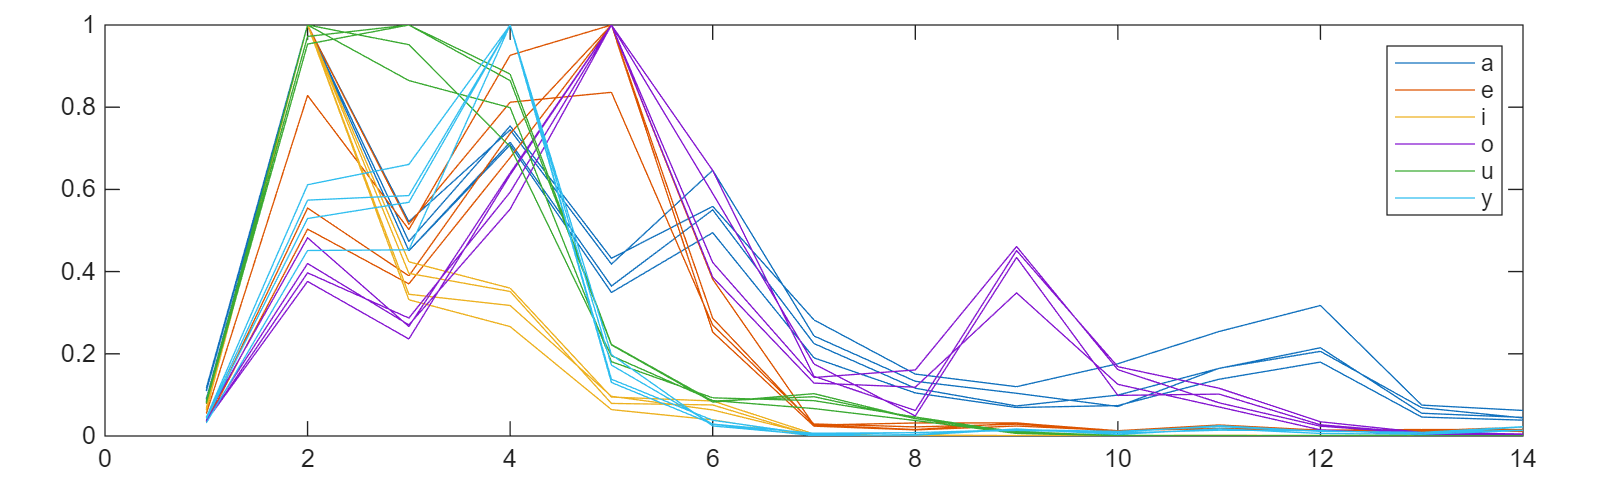

fh = figure("Position", [0 0 1000 300]);
tiledlayout(1,1,'TileSpacing','Compact','Padding','Compact');
nexttile;
colors = lines(length(labels));
first_lines = zeros(1, length(labels));
% ids = sel(:,4) == 4;
% feats(ids, 4:6) = 0;
% feats(ids, 8:10) = feats(ids, 8:10)*2;
for k=1:length(labels)
    ids = sel(:,4) == k;
    h = plot(feats(ids, :)', Color=colors(k, :), LineStyle='-', DisplayName=labels(k));
    first_lines(k) = h(1);
    hold on;
end
legend(first_lines);

# Komentarz

Ogólnie wektory cech poszczególnych głosek nie są wystarczająco odseparowane:

- 'o' pokrywa się z 'e'

- 'u' pokrywa się z 'i', 'a'

Ta nierozróżnialność sprawiała wiele problemów w klasyfikacją głosek. Rozwiązaniem mogłobybyć nagranie jeszcze lepszego nagrania 'aeiouy', ale po wielu próbach nie udało się rozwiązać problemu.

**Wzajemne odległości między wektorami - wybór metryki ma znaczenie!**

#### Odległóść euklidesowa

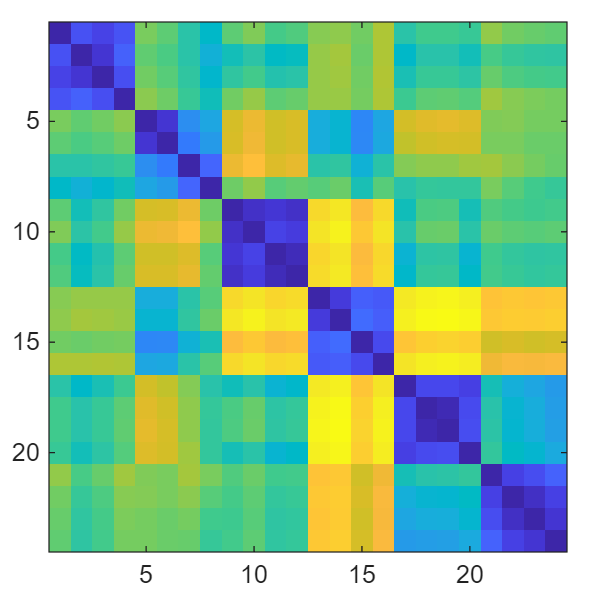

figure("Position", [0 0 300 300]);
tiledlayout(1,1,'TileSpacing','Compact','Padding','Compact');
nexttile;
imagesc(pdist2(feats, feats, 'euclidean'));

#### Odległóść cosinusowa

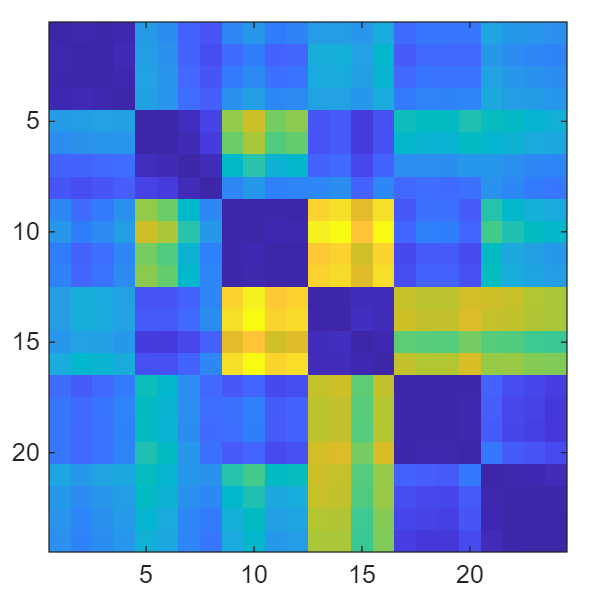

figure("Position", [0 0 300 300]);
tiledlayout(1,1,'TileSpacing','Compact','Padding','Compact');
nexttile;
imagesc(pdist2(feats, feats, 'cosine'));

#### Odległóść EMD

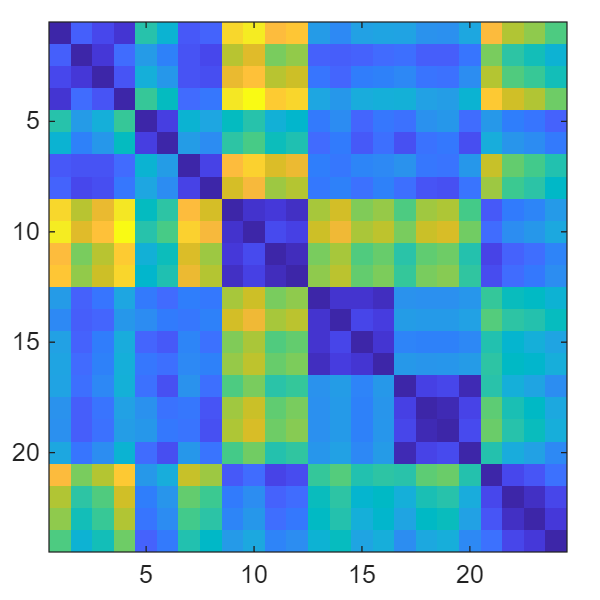

figure("Position", [0 0 300 300]);
tiledlayout(1,1,'TileSpacing','Compact','Padding','Compact');
nexttile;
imagesc(distEmd(feats, feats));

# Komentarz

W naszym przypadku najlepszym wyborem okazuje się być dystans euklidesowy. Dla sąsiadujących samogłosek dystans jest najwyższy.

## Analiza nagrania

### Wczytanie nagrania

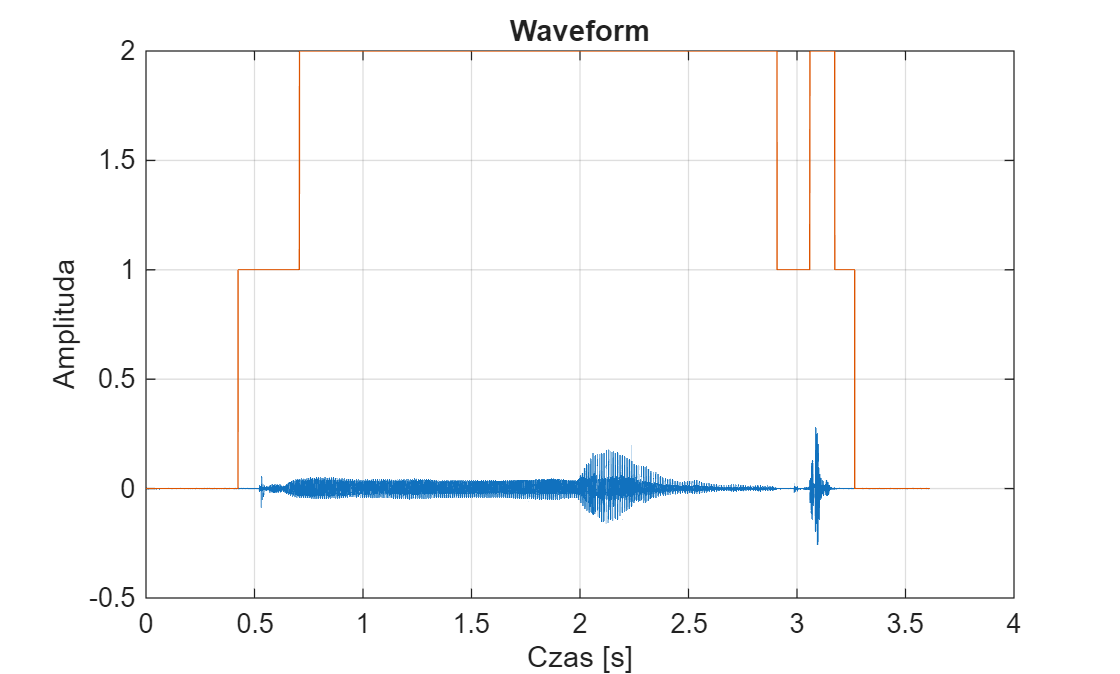

[x, fs] = audioread("slowa/kijek1.wav");
% [x, fs] = audioread("aeiouy.wav");
t = (0:length(x)-1) / fs;

figure;
plot(t, x, 'LineWidth', 0.5);
xlabel('Czas [s]');
ylabel('Amplituda');
title('Waveform');
grid on;
hold on;
labels = label(x, fs);
plot(t, labels)

# Komentarz

Program dobrze klasyfikuje ciszę, fragmenty dźwięczne oraz bezdźwięczne.

### Segmentacja głosek dźwięcznych w nagraniu

Funkcja geVoicedSegments powinna zwracać macierz, w której każdy wiersz odpowiada znalezionej głosce dźwięcznej, a w kolumnach są po kolei:

- indeks pierwszej próbki 

- indeks ostatniej próbki

- częstotliwość bazowa

s = getVoicedSegments(x, fs);

### Wyznaczenie wektorów cech dla poszczególnych głosek

Algorytm identyczny z użytym do wyznaczenia cech wzorcowych:

- wyznaczenie spektrum sygnału i jego aplitudy

- wybór wartości odpowiadających harmonicznym

- normalizacja wartości

s_count = size(s, 1);
 
feat = zeros(s_count, n_peaks);
for seg = 1:s_count
    t1 = s(seg, 1);
    t2 = s(seg, 2);
    f0 = s(seg, 3);
    tmp = x(t1:t2);
    [f, A] = getAmp(tmp, fs);
    
    tmp_f = interp1(f, A, (1:n_peaks) * f0);
    feat(seg, :) = tmp_f / max(tmp_f);
end

### Odległości pomiędzy próbkami z nagrania a wzorcem

figure("Position", [0 0 1000 200]);
tiledlayout(1,1,'TileSpacing','Compact','Padding','Compact');
nexttile;
d = pdist2(feat, feats, 'euclidean')

d =     1.0005    0.8194    0.8862    1.0237    1.2102    1.2215    1.2813    1.0544    0.1373    0.0808    0.2102    0.1799    1.3942    1.4465    1.2966    1.3935    0.8283    0.9782    0.9875    0.8353    0.9629    0.9489    0.9376    0.9526
    1.5669    1.4360    1.4710    1.5658    1.5059    1.5411    1.7107    1.6037    1.1844    1.1721    1.2081    1.1955    1.6031    1.6457    1.5474    1.5876    1.5075    1.5950    1.6076    1.5189    1.3390    1.3741    1.3886    1.4226


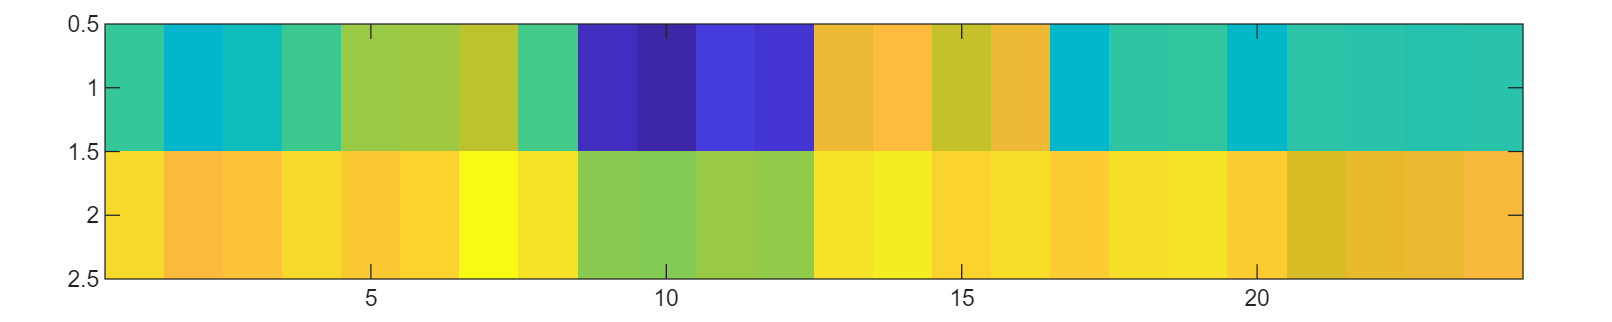

imagesc(d);

### Klasyfikacja próbek

ret = [];
labels = ['a','e','i','o','u','y'];

prev_end = 0;
silence_thr = round(0.05 * fs);

dist_typ = "euclidean";

for seg = 1:s_count
    t1 = s(seg,1);
    t2 = s(seg,2);

    if t1 - prev_end > silence_thr && prev_end ~= 0
        ret = [ret, ' '];
    end

    query = feat(seg,:);
    cls = classify(query, feats, sel(:,4), dist_typ);

    ret = [ret, labels(cls)];

    prev_end = t2;
end
ret

ret = 'i i'

word = get_word(ret)

word = "NULL"

# Podsumowanie

Pogram poprawnie rozpoznaje niektóre słowa. Szczególnie dobrze idzie rozpoznawanie słowa 'prawo'. 

## Funkcje do implementacji

function s = getVoicedSegments(x, fs)
% lista segmentów dźwięcznych, opisana kolejno przez:
% - indeks pierwszej próbki
% - indeks ostatniej próbki
% - częstotliwość bazowa

    % Wyznaczanie etykiet: 0=cisza, 1=bezdźwięczna, 2=dźwięczna
    labels = label(x, fs);

% Długość okienka do pitchwin (200 ms)
    win = round(fs * 0.2);

% Obliczenie f0 dla całego sygnału
    f0 = pitchwin(x, fs, win);

% Szukanie segmentów dźwięcznych (etykieta == 2)
    voiced = labels == 2;
    voiced = movmean(double(voiced), round(fs*0.03)) > 0.5;

% Wyznaczanie początków i końców ciągłych segmentów
    diff_voiced = diff([0; voiced(:); 0]);
    starts = find(diff_voiced == 1);   % indeksy początków
    ends   = find(diff_voiced == -1) - 1; % indeksy końców

    s = zeros(length(starts), 3);
    for i = 1:length(starts)
        idx_start = starts(i);
        idx_end   = ends(i);

% Wyznaczanie f0 dla segmentu: mediana niezerowych wartości
        f0_seg = f0(idx_start:idx_end);
        f0_nonzero = f0_seg(f0_seg > 0);

        if isempty(f0_nonzero)
            f0_mean = 0;
        else
            f0_mean = median(f0_nonzero);
        end

        s(i, :) = [idx_start, idx_end, f0_mean];
    end
end

function cls = classify(query, features, ids, typ)
% klasyfikacja pojedynczej próbki
% - query: badany wektor cech Nx1
% - features: wektory treningowe (referencyjne) NxK
% - ids: identyfikatory klasy Nx1
    if typ == "EMD"
        d = distEmd(query, features);
    else
        d = pdist2(query, features, typ);
    end
    [~, min_id] = min(d, [], 2);
    cls = ids(min_id);
end

## Funkcje pomocnicze

function [f, A] = getAmp(x, fs)
    L = floor(length(x) / 2) * 2;
    Y = fft(x);     % transformata Fouriera

    A = abs(Y);     % amplituda sygnału

    A = A/L;        % normalizacja amplitudy

    A = A(1:L/2+1); % wycięcie istotnej części spektrum
    A(2:end-1) = 2*A(2:end-1);

    f_step = fs/L;     % zmiana częstotliwości
    f = 0:f_step:fs/2; % oś częstotliwości do wykresu
end

function D = distEmd( X, Y )
    % source: http://www.cs.columbia.edu/~mmerler/project/code/pdist2.m

    Xcdf = cumsum(X,2); 
    Ycdf = cumsum(Y,2);
    
    m = size(X,1);  n = size(Y,1);
    mOnes = ones(1,m); D = zeros(m,n);
    for i=1:n
      ycdf = Ycdf(i,:);
      ycdfRep = ycdf( mOnes, : );
      D(:,i) = sum(abs(Xcdf - ycdfRep),2);
    end

end

function f0 = pitchwin(x, fs, win)
    f0 = zeros(length(x), 1);

    f_max = 300;
    f_min = 70;
    lag_min = round(fs / f_max);
    lag_max = round(fs / f_min);

    hop = round(fs * 0.005);

    centers = [];
    f0_vals = [];

    for i = 1:hop:length(x)-win
        sample = x(i:i+win-1);
        sample = sample - mean(sample);

        [c, lags] = xcorr(sample, 'normalized');

        valid = (lags > lag_min) & (lags < lag_max);
        c_v = c(valid);
        lags_v = lags(valid);

        [pks, loc] = findpeaks(c_v, 'MinPeakProminence', 0.2, 'MinPeakWidth', 3);

        center = i + floor(win/2);
        if ~isempty(pks)
            [~, loc_of_max] = max(pks);
            best_lag = lags_v(loc(loc_of_max));
            centers(end+1) = center;
            f0_vals(end+1) = fs / best_lag;
        end
    end

    % Interpolate back to full resolution
    if ~isempty(centers)
        all_idx = 1:length(x);
        f0 = interp1(centers, f0_vals, all_idx, 'linear', 0)';
    end
end


function zcr = zerocrossrate(x)
    zc = diff(sign(x));
    zcr = sum(zc ~= 0) / length(x);
end

function labels = label(x, fs)
    win = round(fs * 0.2);
    
    % Energia
    ste = conv(x.^2, ones(1,win), 'same');
    ste = ste / max(ste);
    str = sqrt(ste);
    
    % ZCR
    x1 = x;
    x2 = [0; x(1:end-1)];
    diff = sign(x1) ~= sign(x2);
    zcr = conv(diff, ones(1, win) / win, "same");
    
    % Progi
    energy_th = 0.01;
    zcr_th = 0.05;
    
    labels = zeros(size(x));
    
    % cisza
    labels(str < energy_th) = 0;
    
    % bezdźwięczne
    labels((zcr >= zcr_th) & (str >= energy_th)) = 1;
    
    % dźwięczne
    labels((zcr < zcr_th) & (str >= energy_th)) = 2;
end

function word = get_word(vowelStr)
    vowels = strsplit(vowelStr);

    dict = {
        'prawo', {'a','o'};
        'lewo',  {'e','o'};
        'gora',  {'o','a'};
        'doly',   {'o', 'y'}      
        };

    word = '';

    for i = 1:size(dict,1)
        pattern = dict{i,2};

        if length(pattern) ~= length(vowels)
            continue;
        end

        if all(strcmp(pattern, vowels))
            word = dict{i,1};
            return;
        end
    end
    
    word = "NULL";
end